clear variables;
close all;

% Глобальная структура, содержащая индексы переменных в общем векторе состояния
global u_range;
global F M;
global state;
global log;

u_range = struct();
u_range.m = 1;          % Масса ракеты
u_range.r = 2:3;        % Вектор положения ракеты
u_range.v = 4:5;        % Вектор скорости ракеты
u_range.alpha = 6;       % Угол наклона ракеты
u_range.omega =7;       % Угловая скорасть вращения ракеты
u_range.size = [7, 1];  % Размер вектора состояния

% Структура хранящая векторы сил, действующих на ракету
F = struct();

% Структура хранящая моменты сил, действующих на ракету
M = struct();

% Структура хранящая фазы полёта и управляющие воздействия
state = struct();

% Таблицы для хранения зависимости параметров расчёта от времени.
% В данных таблицах будут храниться значения, не входящие в вектор состояния ракеты
log.state = table();
log.phases = table();
log.F = table();
log.M = table();

% Начальный вектор состояния ракеты
u0 = zeros(u_range.size);   % Вектор нач. сост. - столбец нулей
u0(u_range.m) = 20e3;       % Задание стартовой массы ракеты с учетом топлива

options = odeset(...
    "MaxStep",1,...                 Макс. шаг интегрирования в секундах
    "Refine",1,...                  Отключение доп. промежуточных шагов
    "OutputFcn", @falcon_output...    Ссылка на функцию вывода
    );

% Настройка состояния системы управления ракеты

state.phase = 0;
state.phaseStart = 0;
state.subPhase = 0;
state.subPhaseStart = 0;
state.phaseStarted = false;

falcon_controlFcn(0,u0);

%  диф. уравнения
[t, u] = ode45(...
    @falcon_ode, ...          Ссылка на функцию, определяющую ДУ
    [0 600],...             Диапазон времени
    u0,...                  Начальные данные
    options);

% Извлечение переменных в удобном для использования формате
m = u(:, u_range.m);
r = u(:, u_range.r);
v = u(:, u_range.v);
alpha = u(:, u_range.alpha);
omega = u(:, u_range.omega);

x = r(:,1);
y = r(:,2);
Vx = v(:,1);
Vy = v(:,2);
tang = pi/2 - atan2(Vy,Vx);     % Касательная к траектории
V_norm = sqrt(Vx.^2 + Vy.^2);    % Модуль скорости

N = length(t);





## Визуализация

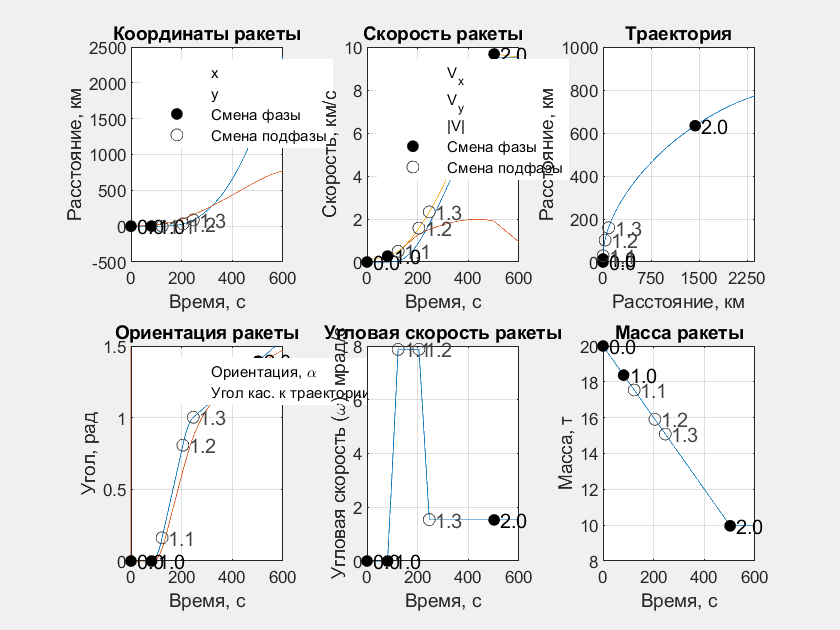

myfigure('Белый Глеб');

subplot(2,3,1);
plot(t,r/1e3);
plotPhaseChangePoint(t,[t x/1e3]);
xlabel('Время, с');
ylabel('Расстояние, км');
title('Координаты ракеты');
legend({'x','y','Смена фазы','Смена подфазы'},'Location','northwest');
grid on;
axis([0 600 -500 2500]);
set(gca, 'XTick', 0:200:600);
set(gca, 'YTick', -500:500:2500);



subplot(2,3,2);
plot(t,[v(:,1)/1e3 v(:,2)/1e3 sqrt(v(:,1).^2+v(:,2).^2)/1e3]);
plotPhaseChangePoint(t,[t sqrt(v(:,1).^2+v(:,2).^2)/1e3]);
legend({'V_x','V_y','|V|','Смена фазы','Смена подфазы'},'Location','northwest');
xlabel('Время, с');
ylabel('Скорость, км/с');
title('Скорость ракеты');
grid on;
axis([0 600 0 10]);
set(gca, 'XTick', 0:200:600);
set(gca, 'YTick', 0:2:10);

subplot(2,3,3);
plot(x/1e3, y/1e3);
plotPhaseChangePoint(t,[x/1e3 y/1e3]);
xlabel('Расстояние, км');
ylabel('Расстояние, км');
title('Траектория');
grid on;
axis([0 2.3679e+03 0 1000]);
set(gca, 'XTick', 0:750:2250);
set(gca, 'YTick', 0:200:1000);

subplot(2,3,4);
plot(t,[alpha tang]);
plotPhaseChangePoint(t,[t alpha]);
legend({'Ориентация, \alpha','Угол кас. к траектории'},'Location','northwest');
xlabel('Время, с');
ylabel('Угол, рад');
title('Ориентация ракеты');
grid on;
axis([0 600 0 1.5]);
set(gca, 'XTick', 0:200:600);
set(gca, 'YTick', 0:0.5:1.5);


subplot(2,3,5);
plot(t,omega*1e3);
plotPhaseChangePoint(t,[t omega*1e3]);
xlabel('Время, с');
ylabel('Угловая скорость (\omega), мрад/с');
title('Угловая скорость ракеты');
grid on;
axis([0 600 0 8]);
set(gca, 'XTick', 0:200:600);
set(gca, 'YTick', 0:2:8);

subplot(2,3,6);
plot(t,m/1e3);
plotPhaseChangePoint(t,[t m/1e3]);
xlabel('Время, с');
ylabel('Масса, т');
title('Масса ракеты');
grid on;
axis([0 600 8 20]);
set(gca, 'XTick', 0:200:600);
set(gca, 'YTick', 8:2:20);

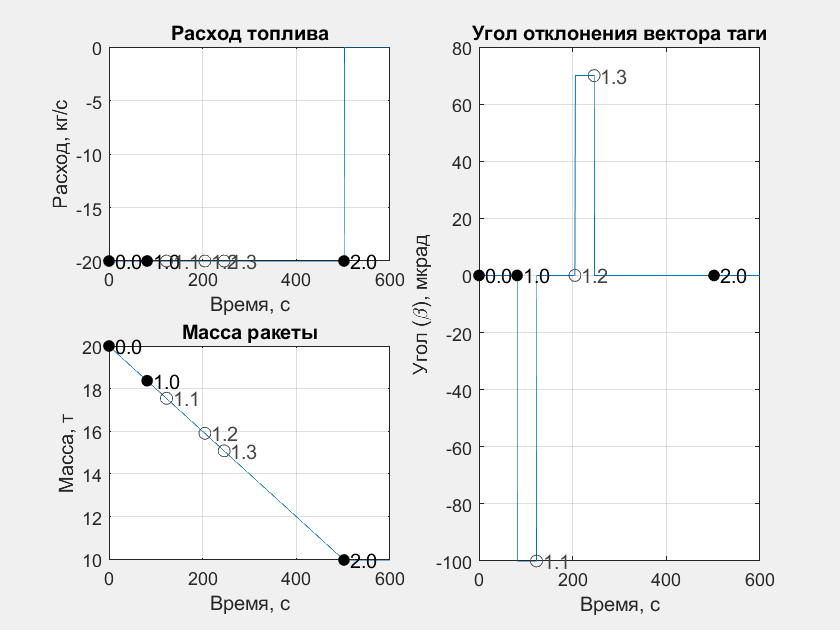




myfigure('Параметры ракеты:Белый Глеб');

subplot(2,2,1)
plot(t,log.state.massFlow);
plotPhaseChangePoint(t,[t log.state.massFlow]);
xlabel('Время, с');
ylabel('Расход, кг/с');
title('Расход топлива');
grid on;


subplot(2,2,[2,4])
plot(t,log.state.beta*1e6);
plotPhaseChangePoint(t,[t log.state.beta*1e6]);
xlabel('Время, с');
ylabel('Угол (\beta), мкрад');
title('Угол отклонения вектора таги');
grid on;


subplot(2,2,3)
plot(t,m/1e3);
plotPhaseChangePoint(t,[t m/1e3]);
xlabel('Время, с');
ylabel('Масса, т');
title('Масса ракеты');
grid on;

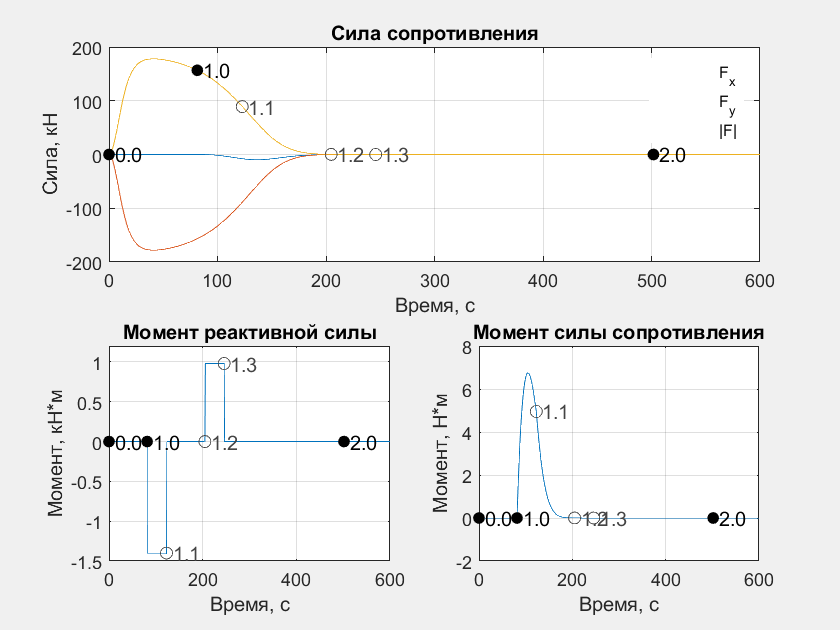



myfigure('Силы и моменты:Белый Глеб');

subplot(2,2,[1,2])
plot(t,[log.F.resist(:,1) log.F.resist(:,2) sqrt(log.F.resist(:,1).^2 + log.F.resist(:,2).^2)]/1e3);
plotPhaseChangePoint(t,[t sqrt(log.F.resist(:,1).^2 + log.F.resist(:,2).^2)/1e3]);
xlabel('Время, с');
ylabel('Сила, кН');
title('Сила сопротивления');
grid on;

legend({'F_x','F_y','|F|'},'Location','northeast');

subplot(2,2,3)
plot(t, log.M.jet/1e3);
plotPhaseChangePoint(t,[t log.M.jet/1e3]);
xlabel('Время, с');
ylabel('Момент, кН*м');
title('Момент реактивной силы');
grid on;
axis([0 600 -1.5 1.2]);


subplot(2,2,4)
plot(t, log.M.resist);
plotPhaseChangePoint(t,[t log.M.resist]);
xlabel('Время, с');
ylabel('Момент, Н*м');
title('Момент силы сопротивления');
grid on;
axis([0 600 -2 8]);

function f = myfigure(name,varargin)
    f = figure(...
        "Visible","on",...       Принудительное отображение в отдельном окне
        "NumberTitle", "off",... Скрытие надписи "figure:"
        "Name",name,...          Новое имя окна
        varargin{:}...           Передача доп. арг. пользователю
        );
end

function plotPhaseChangePoint(t,r1)
    global log;
    
    hold on
    
    sz =size(log.phases.t);
    x = zeros(sz);
    y = zeros(sz);
    labels = cell(sz);           % Текстовые метки точек
    descriptions = cell(sz);     % Подробное описание точек
    phaseChange = false(sz);     % Вектор из логических величин, показывающий, являестя ли данная запись сменой фаз
    
    for i = 1:height(log.phases)
       j = find(t >= log.phases.t(i), 1);
       x(i) = r1(j,1);
       y(i) = r1(j,2);
       
       % Формирование подписи к точке
       labels(i) = cellstr([' ' num2str(log.phases.phase(i)) '.' num2str(log.phases.subPhase(i))]);
       descriptions(i) = log.phases.description(i);
       
       % Определение является ли данная точка сменой састояния
       phaseChange(i) = log.phases.subPhase(i) == 0;
    end
    
    subPhaseChange = ~phaseChange; % Вектор из логических величин, показывающи1, является ли данная запись ...
    
    % Подписи к точкам (функция text отображает сразу весь массив подписей)
    text(x(phaseChange), y(phaseChange), labels(phaseChange), "FontSize", 10, "Color", "k");
    text(x(subPhaseChange), y(subPhaseChange), labels(subPhaseChange), "FontSize", 10, "Color", '#444444');
    
    % Отображение независимо точек смены состояний и подсостояний разными стилями
    p1 = plot(x(phaseChange), y(phaseChange), 'k.', "MarkerSize", 20, "DisplayName", 'Смена фазы');
    p2 = plot(x(subPhaseChange), y(subPhaseChange), 'o', 'Color', '#444444', "DisplayName", 'Смена подфазы');
    
    % Внимание, интересно! Добавление расширенной информации к точке
    row1 = dataTipTextRow('Фаза', descriptions(phaseChange));
    row2 = dataTipTextRow('Подфаза', descriptions(subPhaseChange));
    p1.DataTipTemplate.DataTipRows(end +1) = row1;
    p2.DataTipTemplate.DataTipRows(end +1) = row2;    
end